syms a2 b1 c1 c2 k x y

general = [(-2*b1*x/k) + b1 - c1*y -c1*x ; c2*y c2*x - a2];


A_ss1 = [b1 0 ; 0 -a2];
[EV1,ev1] = eig(A_ss1)

$$EV1 = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

$$ev1 = \left(\begin{array}{cc} b_{1} & 0\\ 0 & -a_{2} \end{array}\right)$$

a_1 = subs(ev1,[b1,a2,c1,c2,k],[1,0.5,0.01,0.005,1000]);
A_1 = subs(EV1,[b1,a2,c1,c2,k],[1,0.5,0.01,0.005,1000])

$$A\_1 = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$


A_ss2 = [-a2*b1/(k*c2) -a2*c1/c2 ; (c2*b1/c1)*(1-(a2/(c2*k))) 0]

$$A\_ss2 = \left(\begin{array}{cc} -\frac{a_{2}\,b_{1}}{c_{2}\,k} & -\frac{a_{2}\,c_{1}}{c_{2}}\\ -\frac{b_{1}\,c_{2}\,\left(\frac{a_{2}}{c_{2}\,k}-1\right)}{c_{1}} & 0 \end{array}\right)$$

[EV2,ev2] = eig(A_ss2)

$$EV2 = \begin{array}{l} \left(\begin{array}{cc} \frac{c_{1}\,\left(a_{2}\,b_{1}-\sigma_{1}\right)}{2\,c_{2}\,\left(a_{2}\,b_{1}-b_{1}\,c_{2}\,k\right)} & \frac{c_{1}\,\left(a_{2}\,b_{1}+\sigma_{1}\right)}{2\,c_{2}\,\left(a_{2}\,b_{1}-b_{1}\,c_{2}\,k\right)}\\ 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{a_{2}\,b_{1}\,\left(-4\,{c_{2}}^{2}\,k^{2}+4\,a_{2}\,c_{2}\,k+a_{2}\,b_{1}\right)} \end{array}$$

$$ev2 = \left(\begin{array}{cc} -\frac{a_{2}\,b_{1}-\sqrt{a_{2}\,b_{1}\,\left(-4\,{c_{2}}^{2}\,k^{2}+4\,a_{2}\,c_{2}\,k+a_{2}\,b_{1}\right)}}{2\,c_{2}\,k} & 0\\ 0 & -\frac{a_{2}\,b_{1}+\sqrt{a_{2}\,b_{1}\,\left(-4\,{c_{2}}^{2}\,k^{2}+4\,a_{2}\,c_{2}\,k+a_{2}\,b_{1}\right)}}{2\,c_{2}\,k} \end{array}\right)$$

a_2 = subs(ev2,[b1,a2,c1,c2,k],[1,0.5,0.01,0.005,1000])

$$a\_2 = \left(\begin{array}{cc} -\frac{1}{20}+\frac{\sqrt{179}\,\mathrm{i}}{20} & 0\\ 0 & -\frac{1}{20}-\frac{\sqrt{179}\,\mathrm{i}}{20} \end{array}\right)$$

A_2 = subs(EV2,[b1,a2,c1,c2,k],[1,0.5,0.01,0.005,1000])

$$A\_2 = \left(\begin{array}{cc} -\frac{1}{9}+\frac{\sqrt{179}\,\mathrm{i}}{9} & -\frac{1}{9}-\frac{\sqrt{179}\,\mathrm{i}}{9}\\ 1 & 1 \end{array}\right)$$


A_ss3 = [-b1 -k*c1; 0 k*c2 - a2]

$$A\_ss3 = \left(\begin{array}{cc} -b_{1} & -c_{1}\,k\\ 0 & c_{2}\,k-a_{2} \end{array}\right)$$

[EV3,ev3] = eig(A_ss3)

$$EV3 = \left(\begin{array}{cc} -\frac{c_{1}\,k}{b_{1}-a_{2}+c_{2}\,k} & 1\\ 1 & 0 \end{array}\right)$$

$$ev3 = \left(\begin{array}{cc} c_{2}\,k-a_{2} & 0\\ 0 & -b_{1} \end{array}\right)$$

a_3 = subs(ev3,[b1,a2,c1,c2,k],[1,0.5,0.01,0.005,1000]);
A_3 = subs(EV3,[b1,a2,c1,c2,k],[1,0.5,0.01,0.005,1000]);

syms C1 C2 C3 C4 C5 C6 t
y_ss1 = C1*A_1(:,1)*exp(a_1(1,1)*t) + C2*A_1(:,2)*exp(a_1(2,2)*t);
y_ss2 = C3*A_2(:,1)*exp(a_2(1,1)*t) + C4*A_2(:,2)*exp(a_2(2,2)*t);
y_ss3 = C5*A_3(:,1)*exp(a_3(1,1)*t) + C6*A_3(:,2)*exp(a_3(2,2)*t);

eqn1_ss1 = subs(y_ss1(1),t,0) == 200;
eqn2_ss1 = subs(y_ss1(2),t,0) == 80;

eqn1_ss2 = subs(y_ss2(1),t,0) == 200

$$eqn1\_ss2 = C_{3}\,\left(-\frac{1}{9}+\frac{\sqrt{179}\,\mathrm{i}}{9}\right)-C_{4}\,\left(\frac{1}{9}+\frac{\sqrt{179}\,\mathrm{i}}{9}\right)=200$$

eqn2_ss2 = subs(y_ss2(2),t,0) == 80

$$eqn2\_ss2 = C_{3}+C_{4}=80$$


eqn1_ss3 = subs(y_ss3(1),t,0) == 200;
eqn2_ss3 = subs(y_ss3(2),t,0) == 80;

sol_ss1 = solve([eqn1_ss1,eqn2_ss1],[C1,C2]);
sol_ss2 = solve([eqn1_ss2,eqn2_ss2],[C3,C4]);
sol_ss3 = solve([eqn1_ss3,eqn2_ss3],[C5,C6]);

y1 = subs(y_ss1,[C1,C2],[sol_ss1.C1,sol_ss1.C2])   

$$y1 = \left(\begin{array}{c} 200\,{\mathrm{e}}^{t}\\ 80\,{\mathrm{e}}^{-\frac{t}{2}} \end{array}\right)$$

y2 = subs(y_ss2,[C3,C4],[sol_ss2.C3,sol_ss2.C4])

$$y2 = \begin{array}{l} \left(\begin{array}{c} -\sigma_{2}\,\left(-\frac{1}{9}+\frac{\sqrt{179}\,\mathrm{i}}{9}\right)\,\sigma_{3}+\frac{20\,\sqrt{179}\,\sigma_{1}\,\left(\frac{1}{9}+\frac{\sqrt{179}\,\mathrm{i}}{9}\right)\,\left(-47+2\,\sqrt{179}\,\mathrm{i}\right)\,\mathrm{i}}{179}\\ -\sigma_{2}\,\sigma_{3}-\frac{20\,\sqrt{179}\,\sigma_{1}\,\left(-47+2\,\sqrt{179}\,\mathrm{i}\right)\,\mathrm{i}}{179} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-t\,\left(\frac{1}{20}+\frac{\sqrt{179}\,\mathrm{i}}{20}\right)}\\ \sigma_{2}={\mathrm{e}}^{t\,\left(-\frac{1}{20}+\frac{\sqrt{179}\,\mathrm{i}}{20}\right)}\\ \sigma_{3}=-40+\frac{940\,\sqrt{179}\,\mathrm{i}}{179} \end{array}$$

y3 = subs(y_ss3,[C5,C6],[sol_ss3.C5,sol_ss3.C6])

$$y3 = \left(\begin{array}{c} \frac{3800\,{\mathrm{e}}^{-t}}{11}-\frac{1600\,{\mathrm{e}}^{\frac{9\,t}{2}}}{11}\\ 80\,{\mathrm{e}}^{\frac{9\,t}{2}} \end{array}\right)$$

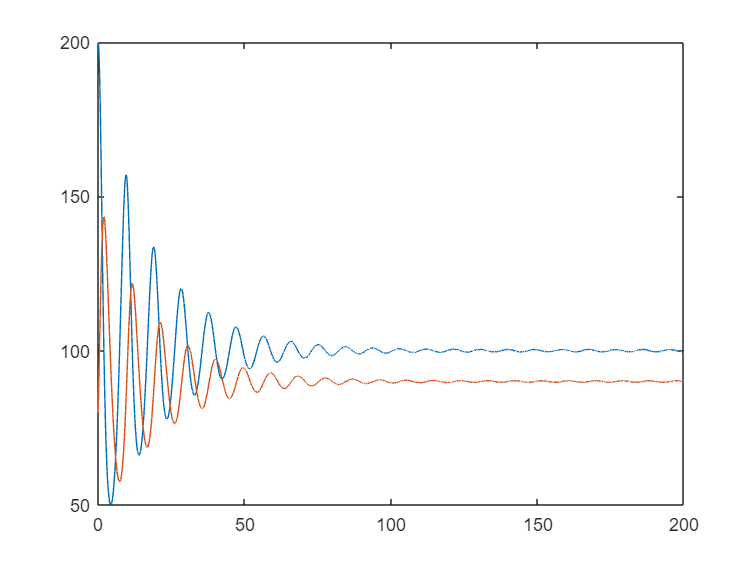

x = [200 80]';
tspan = 0:0.01:200;
[X,Y] = ode45(@ODEfcn,tspan,x);
plot(X,Y,"-");

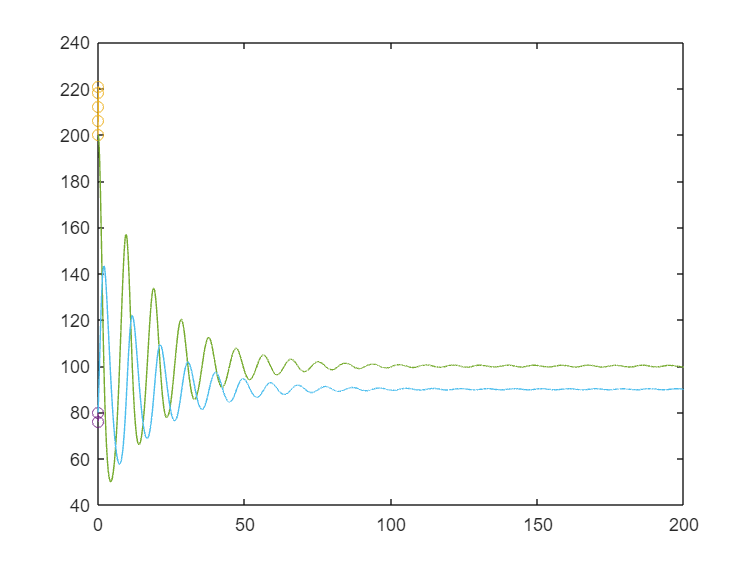

hold on
fplot(y1,[0 0.1],"-o");
plot(X,Y,"-");
hold off

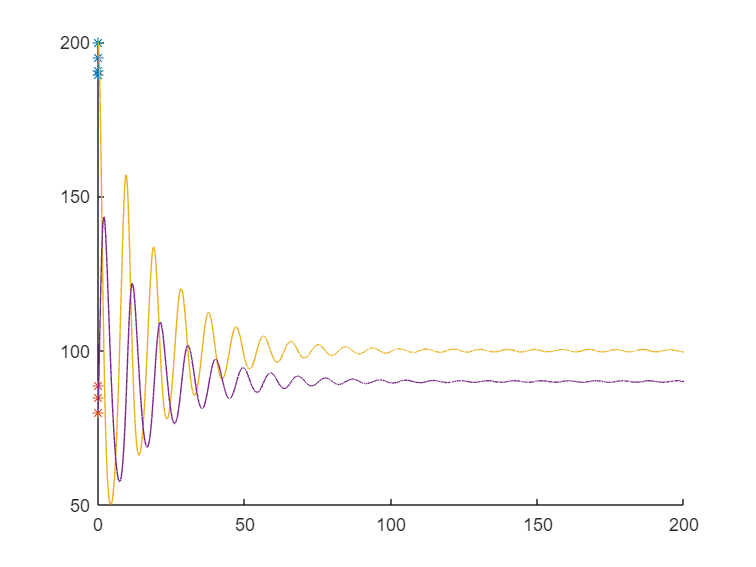

clf
hold on
fplot(y2,[0 0.1],"-*");
plot(X,Y,"-");
hold off

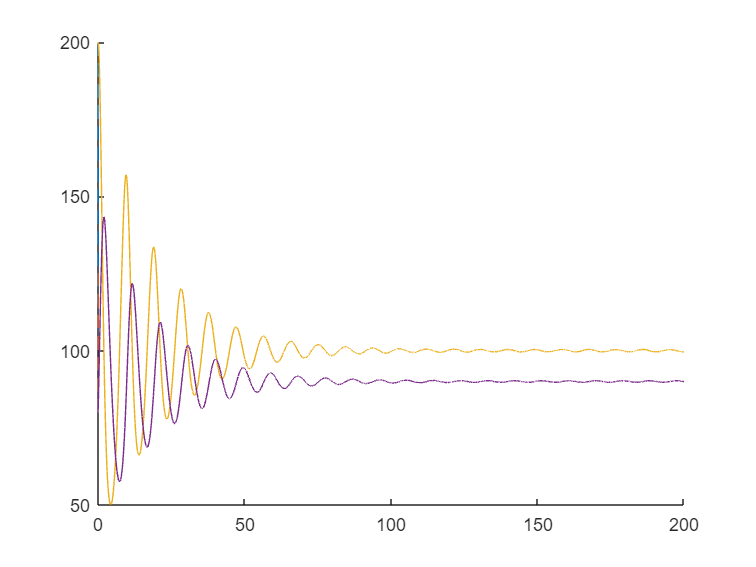

clf
hold on
fplot(y3,[0 0.1],"--");
plot(X,Y,"-");
hold off

clf

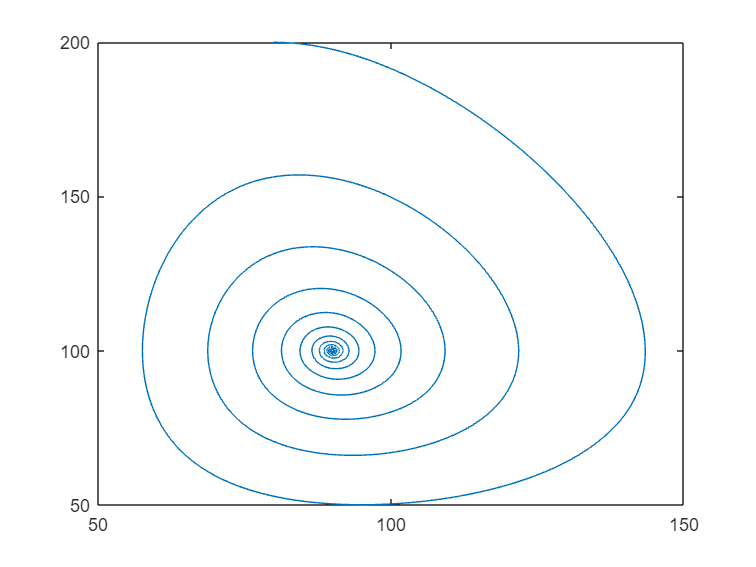

plot(Y(:,2),Y(:,1),"-")